# Praktikum 2 - Shift 2 Kamis

`16 September 2021`

`Nama : ``Asisten Praktikum`

`NIM  :`

## Nomor 1

Tuliskan asumsi-asumsi, barisan akar, dan syarat penghentian yang digunakan pada metode Newton Raphson!

**Jawaban : **

Asumsi yang digunakan adalah untuk suatu fungsi kontinu $f\left(x\right)$ dan tebakan awal $x_0$, maka $f^{\prime } \left(x_0 \right)$ ada dan tidak nol. Barisan akar pada metode Newton-Raphson adalah 

### 
$$x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$$


dengan kriteria/syarat penghentian

### 
$$\left|\frac{c_{k+1} -c_k }{c_k }\right|<\varepsilon$$


dengan hampiran akar yang dipilih adalah nilai $c_k$ terakhir.

## Nomor 2

Apa perbedaan utama antara metode sekan/tali busur dengan metode Newton-Raphson? Kapan metode sekan/tali busur lebih cocok digunakan daripada metode Newton-Raphson?

**Jawaban :**

Perbedaan utamanya adalah metode Newton-Raphson menggunakan turunan fungsi untuk menghitung gradien dari dua titik secara eksak, sedangkan metode sekan/tali busur menggunakan metode numerik (beda hingga) untuk memperoleh hasil tersebut.

Umumnya, fungsi dengan turunan yang sulit ditemukan akan lebih mudah diselesaikan menggunakan metode sekan/tali busur.

## Nomor 3

John Lee adalah dewa perjanjian yang menguasai suatu negara, sebut saja negara tersebut adalah LW. Sebagai dewa perjanjian, ia harus memastikan bahwa semua perjanjian jual beli, utang, dan piutang di negaranya adil dan tidak membebankan pihak manapun. Misalkan di negara LW berlaku suku bunga sebesar $i$ per tahun. Suatu hari, John Lee menemukan seorang bankir dan nasabahnya bertengkar karena nasabahnya ingin meminjam uang untuk memulai bisnisnya, tetapi bankir tersebut menagih cicilan per tahun yang terlalu tinggi yang terlalu berat untuk dibayarkan karena tentunya sebuah bisnis tidak akan bisa menghasilkan laba yang besar dalam tahun-tahun pertama operasinya. Dengan menggunakan kebijaksanaannya yang tak terukur, John Lee membuat skema berikut. Misalkan jumlah yang dipinjam dari bankir adalah sebesar $A$, dan di akhir tahun pertama, nasabah tersebut akan membayarkan uang cicilan sebesar $P$. Pada tahun berikutnya, karena bisnis nasabah tersebut sudah diekspektasikan untuk berkembang, ia harus membayar $P+Q$ di akhir tahun, $P+2Q$ di akhir tahun berikutnya, dan begitu seterusnya. Hutang nasabah tersebut dilunasi setelah $n$ tahun, yaitu ketika persamaan berikut terpenuhi

#### 
$$A  = P(1+i)^{-1} + (P+Q)(1+i)^{-2}+(P+2Q)(1+i)^{-3}+...+[P+(n-2)Q](1+i)^{1-n}+[P+(n-1)Q](1+i)^{-n}$$


### 3A

Tunjukkan bahwa $A$ dapat dituliskan ulang sebagai

### 
$$A=\frac{P}{i}\left(1-v^n \right)+\frac{Q}{i}\left(\frac{1-v^n }{i}-{\textrm{nv}}^n \right)$$


dengan $v={\left(1+i\right)}^{-1}$

**Tips :**

-  Misalkan sebuah persamaan baru$B=A\left(1+i\right)$. Kurangi persamaan baru ini dengan persamaan awal untuk membantu anda memperoleh bentuk yang lebih sederhana.

- Gunakan rumus untuk deret geometri.

**Jawaban :***** (Boleh diketik langsung atau foto tulisan anda dan upload ke file ini lewat "Insert > Image")***

Kalikan $A$ dengan $(1+i)$ sehingga diperoleh dua persamaan


$$A  = P(1+i)^{-1} + (P+Q)(1+i)^{-2}+(P+2Q)(1+i)^{-3}+...+[P+(n-2)Q](1+i)^{1-n}+[P+(n-1)Q](1+i)^{-n}$$



$$B=P+(P+Q)(1+i)^{-1}+(P+2Q)(1+i)^{-2}+(P+3Q)^{-3}+...+[P+(n-2)Q](1+i)^{-n+2}+[P+(n-1)Q](1+i)^{-n+1}$$


Dengan mengurangi persamaan $B$ dengan $A$ diperoleh


$$B-A=(1+i)A-A=iA=P+Q(1+i)^{-1}+Q(1+i)^{-2}+...+Q(1+i)^{-(n-1)}-(P+(n-1)Q)(1+i)^{-n}$$



$$iA=P+Q(1+i)^{-1}+...+Q(1+i)^{-(n-1)}+Q(1+i)^{-n}-P(1+i)^{-n}-Qn(1+i)^{-n}$$



$$iA=P[1-(1+i)^{-n}]+Q\left[\sum_{k=1}^n(1+i)^{-k}-n(1+i)^{-n}\right]$$


Misalkan $v=(1+i)^{-1}$, kita punya bahwa $i=\frac{1-v}{v}$. Dengan menggunakan formula untuk deret geometri diperoleh


$$\sum_{k=1}^n(1+i)^{-k}=\sum_{k=1}^nv^k=\frac{v(v^n-1)}{v-1}=\frac{v^n-1}{\frac{v-1}{v}}=\frac{1-v^n}{i}$$


sehingga didapatkan 


$$A=\frac{P}{i}\left[1-v^n \right]+\frac{Q}{i}\left[\frac{1-v^n}{i}-nv^n \right]$$


### 3B

Buatkan sebuah fungsi yang menerima input berupa suku bunga $i$, besar pinjaman $A$, pembayaran awal $P$ dan tambahan pembayaran $Q$ dan mengeluarkan $n$ yaitu berapa tahun yang dibutuhkan untuk melunasi hutang **dengan menggunakan metode Sekan**. Tentunya, karena $n$ belum tentu berupa bilangan bulat, anda dapat membulatkan $n$ yang dihasilkan fungsi anda ke atas. Batasan yang diberikan adalah $0<i<1, P>0, Q>0, A>0$.

Bangun fungsi tersebut pada file `cicilan.m`, dengan input seperti di atas dan output berupa integer $n$.

% Cek jawaban anda disini
i = 0.02;
A = 28480;  
P = 1000;
Q = 500;
fprintf('Waktu yang dibutuhkan untuk melunasi hutang adalah %d tahun', cicilan(i,A,P,Q))

Waktu yang dibutuhkan untuk melunasi hutang adalah 11 tahun

**Tips:**

-  Apa kegunaan fungsi `ceil` di MATLAB?

- Untuk menentukan nilai$n$, bangun fungsi $f\left(n\right)=\frac{P}{i}\left(1-v^n \right)+\frac{Q}{i}\left(\frac{1-v^n }{i}-{\textrm{nv}}^n \right)-A$ dengan anonymous function sebagai bagian dari `cicilan.m`. Tebakan awal yang digunakan juga dapat langsung dimasukan di fungsi tersebut sedemikian sehingga fungsi `cicilan.m` hanya perlu masukan $i,A,P$ dan $Q$ saja.

### 3C

Berdasarkan fungsi yang anda dapatkan di atas, buat plot yang menggambarkan hubungan $i$ dan $n$, dengan $i$ berada di range $[0.01,0.1]$. Dengan parameter-parameter berikut, $A = 80000, P = 3500, Q = 500.$

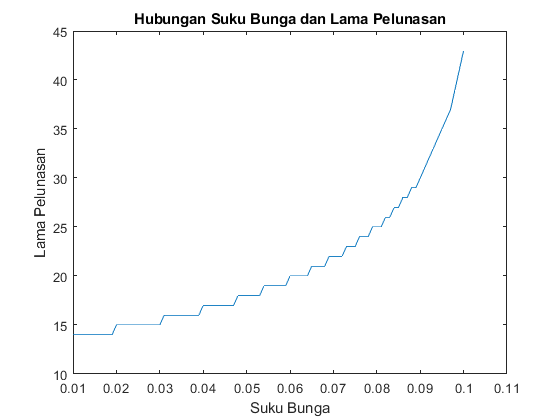

% Tuliskan Jawaban anda dibawah garis ini
% ----------------------------------------
clc;
clear all;

x = 0.01:0.001:0.1;
n = zeros(length(x));
A = 80000;
P = 3500;
Q = 500;
for i=1:length(x)
    y(i) = cicilan(x(i),A,P,Q);
end

figure;
plot(x,y);
xlabel('Suku Bunga')
ylabel('Lama Pelunasan')
title('Hubungan Suku Bunga dan Lama Pelunasan')